**Let's assume y = 0.5e^(0.1x) + 2.    Let's plot this function from x = 0 to 40**

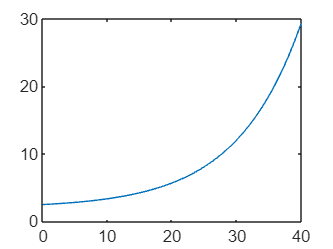

xx = 0 : 1 : 40;
yy = 0.5 * exp(0.1*xx) + 2 ;
plot(xx,yy,'-')

**Now let's assume that we don't know this function, but we know only some points on this function. **

**For example, if we only know 2 points with equal interval between 0 and 40, then we can use linear interpolation (a first-order Lagrange polynomial) to predict the unknown function**

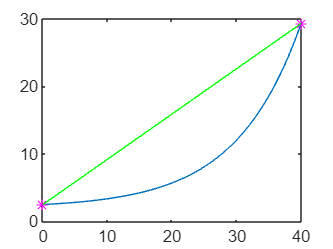

x = linspace(0,40,2) ;
y = 0.5 * exp(0.1*x) + 2 ;
yy1 = Lagrange(x,y,xx);



plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy1,"-g")
hold off


xtest = 15;
y_pred = Lagrange(x,y,xtest)

y_pred = 12.5497

**Now assume that we only know 3 points with equal interval between 0 and 40, then we can use a polynomial interpolation (a second-order Lagrange  polynomial) to predict the unknown function**

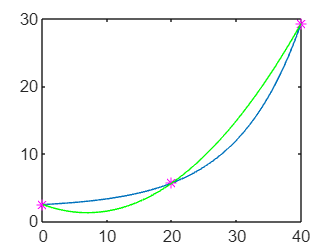

x = linspace(0,40,3) ;
y = 0.5 * exp(0.1*x) + 2 ;
yy2 = Lagrange(x,y,xx);

plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy2,"-g")
hold off


xtest = 15;
y_pred = Lagrange(x,y,xtest)

y_pred = 2.9825

**Now assume that we only know 4 points with equal interval between 0 and 40, then we can use a polynomial interpolation (a 3th-order Lagrange  polynomial) to predict the unknown function**

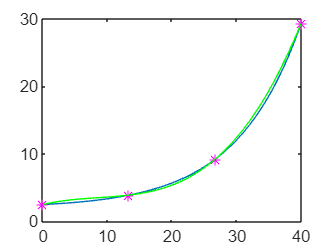

x = linspace(0,40,4) ;
y = 0.5 * exp(0.1*x) + 2 ;
yy3 = Lagrange(x,y,xx);

plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy3,"-g")
hold off


xtest = 15;
y_pred = Lagrange(x,y,xtest)

y_pred = 4.1222